create map

grid = OctoGrid(2,2,2,10);

% add wall
grid.addBox(0.25, 0.25, 0, 0.5, 0.5, 1.5);

grid.addBox(1.4, 0.25, 0, 0.25, 1.4, 1.5);
grid.addBox(0.6, 1.4, 0, 0.8, 0.25, 1.5);

generate kernels

rep_kernels = REP_kernels()

rep_kernels = 1×3 cell array
    {7×7×7 double}    {7×7×7 double}    {7×7×7 double}


display 2d obstacles

image2d = grid.grid(:,:,5)

image2d =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     1     1     1     1     1     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0    

imagesc(image2d)
% Define colors for 0s and 1s
color_0 = [245, 221, 97]/256;  % White for 0s
color_1 = [51, 58, 115]/256  % Black for 1s

color_1 =     0.1992    0.2266    0.4492


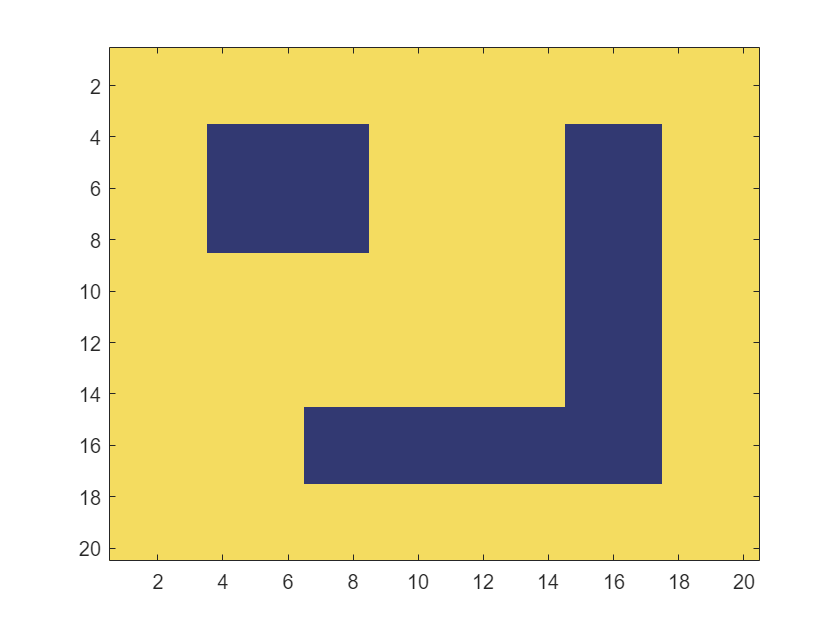


% Create custom colormap
custom_colormap = [color_0; color_1];
colormap(custom_colormap);

field calculation

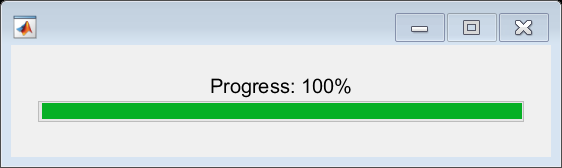

x = 0.1:0.01:2;
y = 0.1:0.01:2;
z = 1;

rep_values_2Dx = [];
rep_values_2Dy = [];

rep_values_2Dx_i = [];
rep_values_2Dy_i = [];

map_matrix = [];

% Initialize waitbar
h = waitbar(0, 'Progress: 0%');

for j = x
    rep_values_1D = [];
    rep_values_1D_i = [];

    map_matrix_1D = [];

    for i = y
%         tic()
        rep_values_1D = [rep_values_1D REP_field_calculation(grid, rep_kernels, [j,i,z],'interpolation_mode', false)'];
        rep_values_1D_i = [rep_values_1D_i REP_field_calculation(grid, rep_kernels, [j,i,z],'interpolation_mode', true)'];

        map_matrix_1D = [map_matrix_1D grid.grid(round(i*grid.resolution), round(j*grid.resolution), 0.5*grid.resolution)];

%         toc()
    end
    rep_values_2Dx = [rep_values_2Dx ; rep_values_1D(1,:)];
    rep_values_2Dy = [rep_values_2Dy ; rep_values_1D(2,:)];

    rep_values_2Dx_i = [rep_values_2Dx_i ; rep_values_1D_i(1,:)];
    rep_values_2Dy_i = [rep_values_2Dy_i ; rep_values_1D_i(2,:)];

    map_matrix = [map_matrix ; map_matrix_1D];

    % Update progress bar
    waitbar(j / x(end), h, sprintf('Progress: %d%%', round(j / x(end) * 100)));
end

create the figure

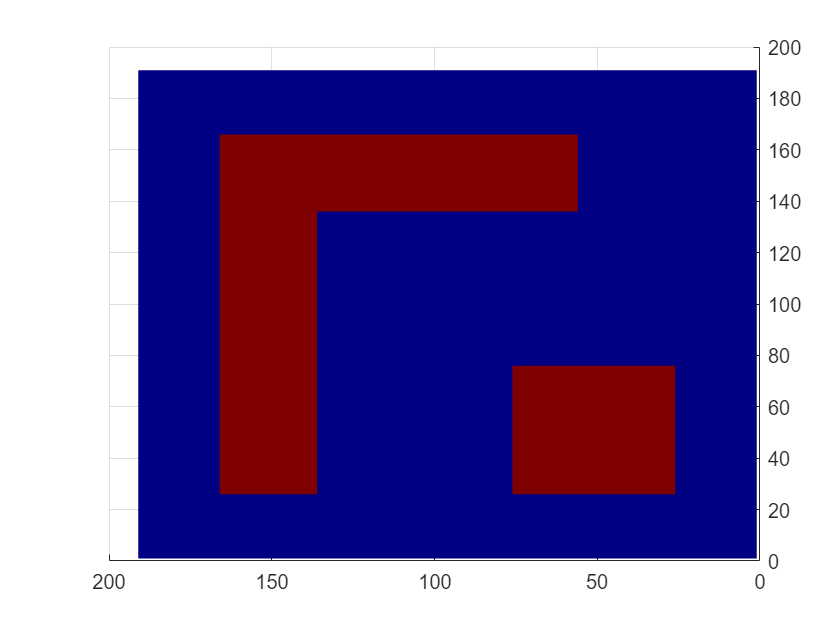

surf(map_matrix*50 + 10, 'EdgeColor', 'none')

% colormap(jet);


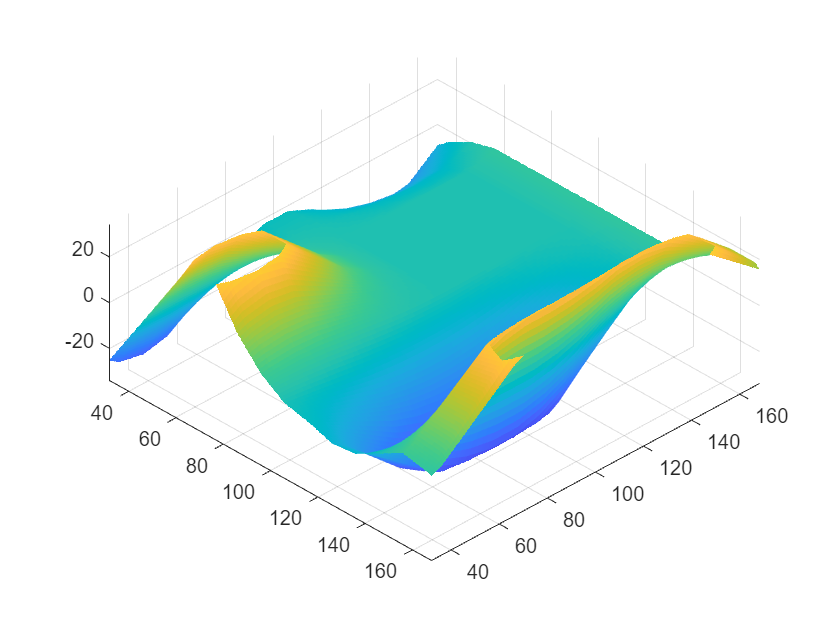

surf(((rep_values_2Dy_i )), 'EdgeColor', 'none')

display vector field

figure()
% Assuming x and y are your 1x191 vectors
[X, Y] = meshgrid(x, y); % This step might be redundant if x and y are already grid vectors

% rep_values_2Dx_i and rep_values_2Dy_i are your 191x191 matrices for the vector components
U = rep_values_2Dx_i;
V = rep_values_2Dy_i;

% U = rep_values_2Dx;
% V = rep_values_2Dy;

% Define step size for sparseness
stepSize = 8; % Adjust this to make the grid more or less sparse

% Sample the matrices to reduce density
X_sparse = X(1:stepSize:end, 1:stepSize:end);
Y_sparse = Y(1:stepSize:end, 1:stepSize:end);
U_sparse = rep_values_2Dx_i(1:stepSize:end, 1:stepSize:end);
V_sparse = rep_values_2Dy_i(1:stepSize:end, 1:stepSize:end);
magnitude_sparse = sqrt(U_sparse.^2+V_sparse.^2)

magnitude_sparse =          0    0.1179    0.7464    3.5748    6.9532    9.7628   11.7630   13.0709   12.2367   10.4926    8.1956    5.9820    3.7500    0.4167         0         0         0         0         0         0         0         0         0         0
    0.1179    0.9664    3.7477   12.3587   18.4446   22.4235   25.1719   26.8725   24.1587   20.3855   16.6771   12.6001    7.0004    0.7778         0         0         0         0         0         0         0         0         0         0
    0.7464    3.7477   11.2430   27.6479   34.3803   38.4080   41.5472   42.3598   37.6159   32.7886   27.1765   18.8112    8.1677    0.9094    0.1886    0.3536    0.4845    0.5148    0.4952    0.5004    0.2621         0         0         0
    3.5748   12.3587   27.6479   39.5273   40.9659   41.8218   42.3328   42.0980   41.1063   36.9429   26.9404   14.8800    5.6906    0.8194    1.6971    3.1820    4.3603    4.6330    4.4570    4.5039    2.3585         0         0         0
    6.9532   18.4

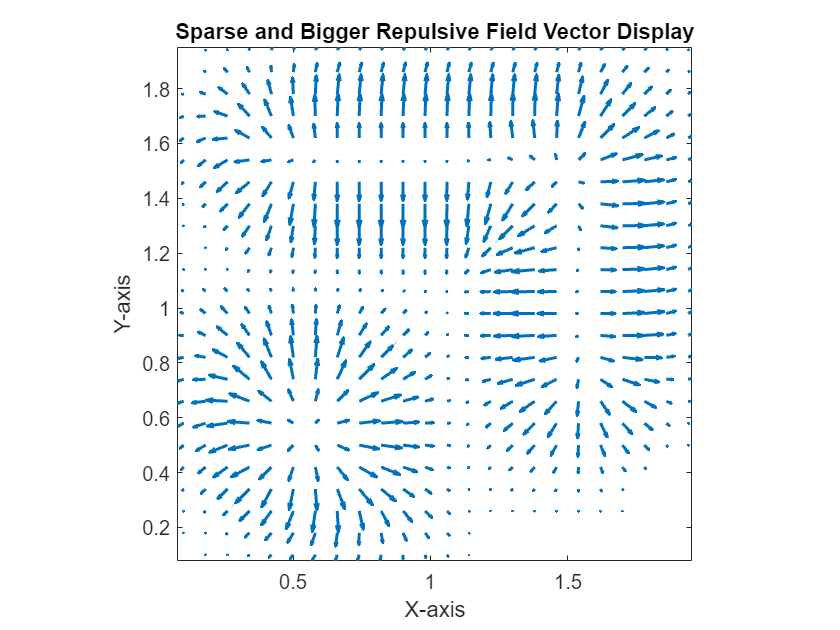


% Plotting the sparser, bigger vector field
quiver(X_sparse, Y_sparse, V_sparse, U_sparse, 'AutoScale', 'on', 'AutoScaleFactor', 0.8, 'LineWidth', 1.5);
title('Sparse and Bigger Repulsive Field Vector Display');
xlabel('X-axis');
ylabel('Y-axis');
axis equal tight;

display vector field using loop, add colors

figure();
% Assuming x and y are your 1x191 vectors
[X, Y] = meshgrid(x, y); % This step might be redundant if x and y are already grid vectors

% rep_values_2Dx_i and rep_values_2Dy_i are your 191x191 matrices for the vector components
U = rep_values_2Dx_i;
V = rep_values_2Dy_i;

% Define step size for sparseness
stepSize = 7; % Adjust this to make the grid more or less sparse

% Sample the matrices to reduce density
X_sparse = X(1:stepSize:end, 1:stepSize:end);
Y_sparse = Y(1:stepSize:end, 1:stepSize:end);
U_sparse = U(1:stepSize:end, 1:stepSize:end);
V_sparse = V(1:stepSize:end, 1:stepSize:end);
scale = 0.001

scale = 1.0000e-03

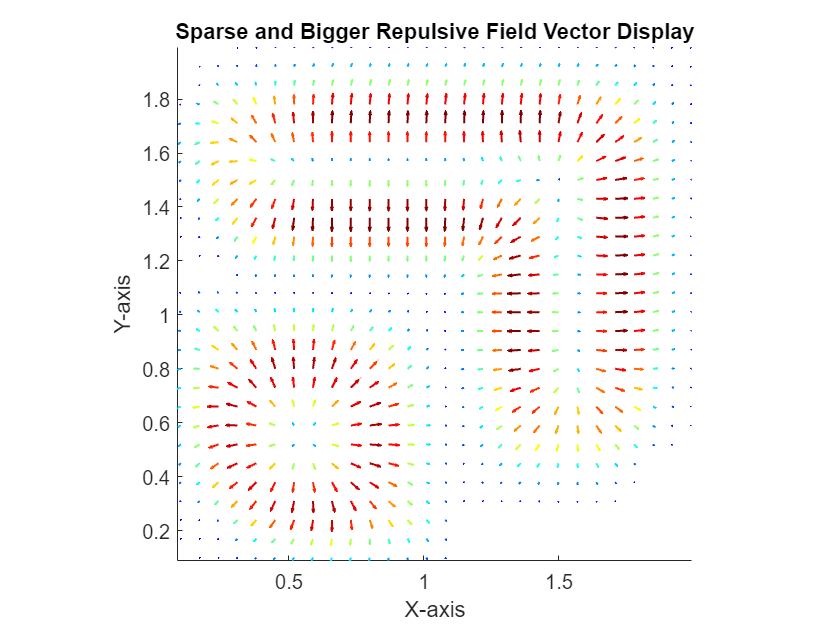

% Calculate the magnitudes of the vectors
magnitudes = sqrt((scale * U_sparse).^2 + (scale * V_sparse).^2);

% Normalize magnitudes for color mapping
maxMagnitude = max(magnitudes(:)); % Find the maximum magnitude
normalizedMagnitudes = magnitudes / maxMagnitude; % Normalize magnitudes to [0, 1]

% Generate a colormap
cmap = jet(256); % Use jet colormap with 256 entries


% Loop over each element in the sparse matrices and plot individually
for i = 1:size(X_sparse, 1)
    for j = 1:size(Y_sparse, 2)
        hold on
        % Map the normalized magnitude to the colormap
        colorIndex = min(max(floor(normalizedMagnitudes(i, j) * size(cmap, 1)), 1), size(cmap, 1));
        arrowColor = cmap(min(colorIndex+25,256), :); % this line was modified to exagerate colors
        
        quiver(X_sparse(i, j), Y_sparse(i, j), scale * V_sparse(i, j), scale * U_sparse(i, j), 'AutoScale', 'off', 'LineWidth', 1, 'Color', arrowColor, 'MaxHeadSize', 2);
    end
end

% Finalizing the plot details
title('Sparse and Bigger Repulsive Field Vector Display');
xlabel('X-axis');
ylabel('Y-axis');
axis equal tight;
hold off; % Release the figure window for other plots